# *E.coli *(iJO1366) "Valine, Leucine, and Isoleucine Metabolism" 

Author: H. Scott Hinton, Utah State University

Reviewer:

## INTRODUCTION

The purpose of this tutorial is to review the basic structure and capabilities of the "Valine, Leucine, and Isoleucine Metabolism" subsystem of the iJO1366* E.coli* model.

## MATERIALS

This tutorial is based on the *Constraint-Based Reconstruction and Analysis* (COBRA) Toolbox [1,2]. To use this tutorial requires the 2016a or newer version of Matlab ([https://www.mathworks.com](https://www.mathworks.com)/) and the COBRA toolbox software that can be downloaded from [https://opencobra.github.io/cobratoolbox/latest/index.html.](https://opencobra.github.io/cobratoolbox/latest/index.html.) The installation instructions and troubleshooting tips are also available on this website.

## **EQUIPMENT SETUP**

Initalize the COBRA toolbox.

initCobraToolbox



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2017
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done.
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  (not installed).
 > Checking if remote can be reached ...  (unsuccessful - no internet connection).
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > Retrieving models ... > The URL https://raw.github.com/snmendoz/Models/master/AntCore.mat cannot be reac

 > Configuring solver environment variables ...
   - [----] ILOG_CPLEX_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [*---] GUROBI_PATH: C:\gurobi750\win64\matlab
   - [---*] TOMLAB_PATH: C:\tomlab_old2\
   - [----] MOSEK_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   Done.
 > Checking available solvers and solver interfaces ... Done.
 > Setting default solvers ... Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved in the default location.

 > Summary of available solvers and solver interfaces

					Support           LP 	 MILP 	   QP 	 MIQP 	  NLP
	----------------------------------------------------------------------
	cplex_direct 	active        	    0 	    0 	    0 	    0 	    -
	dqqMinos     	active        	    0 	    - 	    - 	    - 	    -

Select the optimizer solver.

% changeCobraSolver('glpk','all');
changeCobraSolver('gurobi7','all');


 > Gurobi interface added to MATLAB path.
 > Solver for LP problems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > Solver for MILP problems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > Solver for QP problems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > Solver for MIQP problems has been set to gurobi.
 > Solver gurobi not supported for problems of type NLP. Currently used: matlab 


% changeCobraSolver('tomlab_cplex','all');
% changeCobraSolver('gurobi6','all');

Load the *E.coli *iJO1366 model.

load('iJO1366.mat');
saved_model = iJO1366;
model = saved_model;

## PROCEDURE

## **1.  Valine, Leucine and Isoleucine Metabolism**

The purpose of this tutorial is to identify and review the structure and capabilities of the "Valine, Leucine, and Isoleucine Metabolism" subsystem of the *E.coli* iJO1366 model. This will begin with an overview of the complete subsystem. This overview will be followed by more detailed descriptions of the individaul L-Valine, L-Leucine and L-Isoleucine biosynthesis pathways. It will conclude with a simulation that shows the maximum flux that each these amino acids can produce in an oxidative range from anaerobic to aerobic conditions.

## **2. "**Valine, Leucine, and Isoleucine Metabolism**" Subsystem**

The reactions associated with the "Valine, Leucine, and Isoleucine Metabolism" subsystem can be extracted from the model as shown below.

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
ValineLeucineIsoleucineSubSystems = {'Valine, Leucine, and Isoleucine Metabolism'};
ValineLeucineIsoleucineReactions = model.rxns(ismember(model.subSystems,ValineLeucineIsoleucineSubSystems));
[tmp,ValineLeucineIsoleucine_rxnID] = ismember(ValineLeucineIsoleucineReactions,model.rxns);
reactionNames = model.rxnNames(ValineLeucineIsoleucine_rxnID);
reactionFormulas = printRxnFormula(model,ValineLeucineIsoleucineReactions,0);
% T = table(reactionNames,reactionFormulas,'RowNames',ValineLeucineIsoleucineReactions)
fid = 1;
fprintf(fid,'%-12s %-70s %-50s\r\n','Reaction','Reaction Name','Reaction Formula');

Reaction     Reaction Name                                                          Reaction Formula                                  


[nrows,ncols] = size(ValineLeucineIsoleucineReactions);
for row = 1:nrows
    fprintf(fid,'%-12s %-70s %-50s\r\n',ValineLeucineIsoleucineReactions{row,:}, reactionNames{row,:}, reactionFormulas{row,:});
end

ACHBS        2-aceto-2-hydroxybutanoate synthase                                    2obut_c + h_c + pyr_c  -> 2ahbut_c + co2_c        
ACLS         Acetolactate synthase                                                  h_c + 2 pyr_c  -> alac__S_c + co2_c               
DHAD1        Dihydroxy-acid dehydratase (2,3-dihydroxy-3-methylbutanoate)           23dhmb_c  -> 3mob_c + h2o_c                       
DHAD2        Dihydroxy-acid dehydratase (2,3-dihydroxy-3-methylpentanoate)          23dhmp_c  -> 3mop_c + h2o_c                       
ILETA        Isoleucine transaminase                                                akg_c + ile__L_c  <=> 3mop_c + glu__L_c           
IPMD         3-isopropylmalate dehydrogenase                                        3c2hmp_c + nad_c  -> 3c4mop_c + h_c + nadh_c      
IPPMIa       3-isopropylmalate dehydratase                                          3c2hmp_c  <=> 2ippm_c + h2o_c                     
IPPMIb       2-isopropylmalate hydratase               

**Table 1. **Reaction names and formulas for the  "Valine, Leucine, and Isoleucine Metabolism" subsystem.

The connectivity between these reactions can be visualized through an Escher [3] map of this  "Valine, Leucine, and Isoleucine Metabolism" subsystem as shown below (Valine_Leucine_Isoleucine_Metabolism_Subsystem.json).

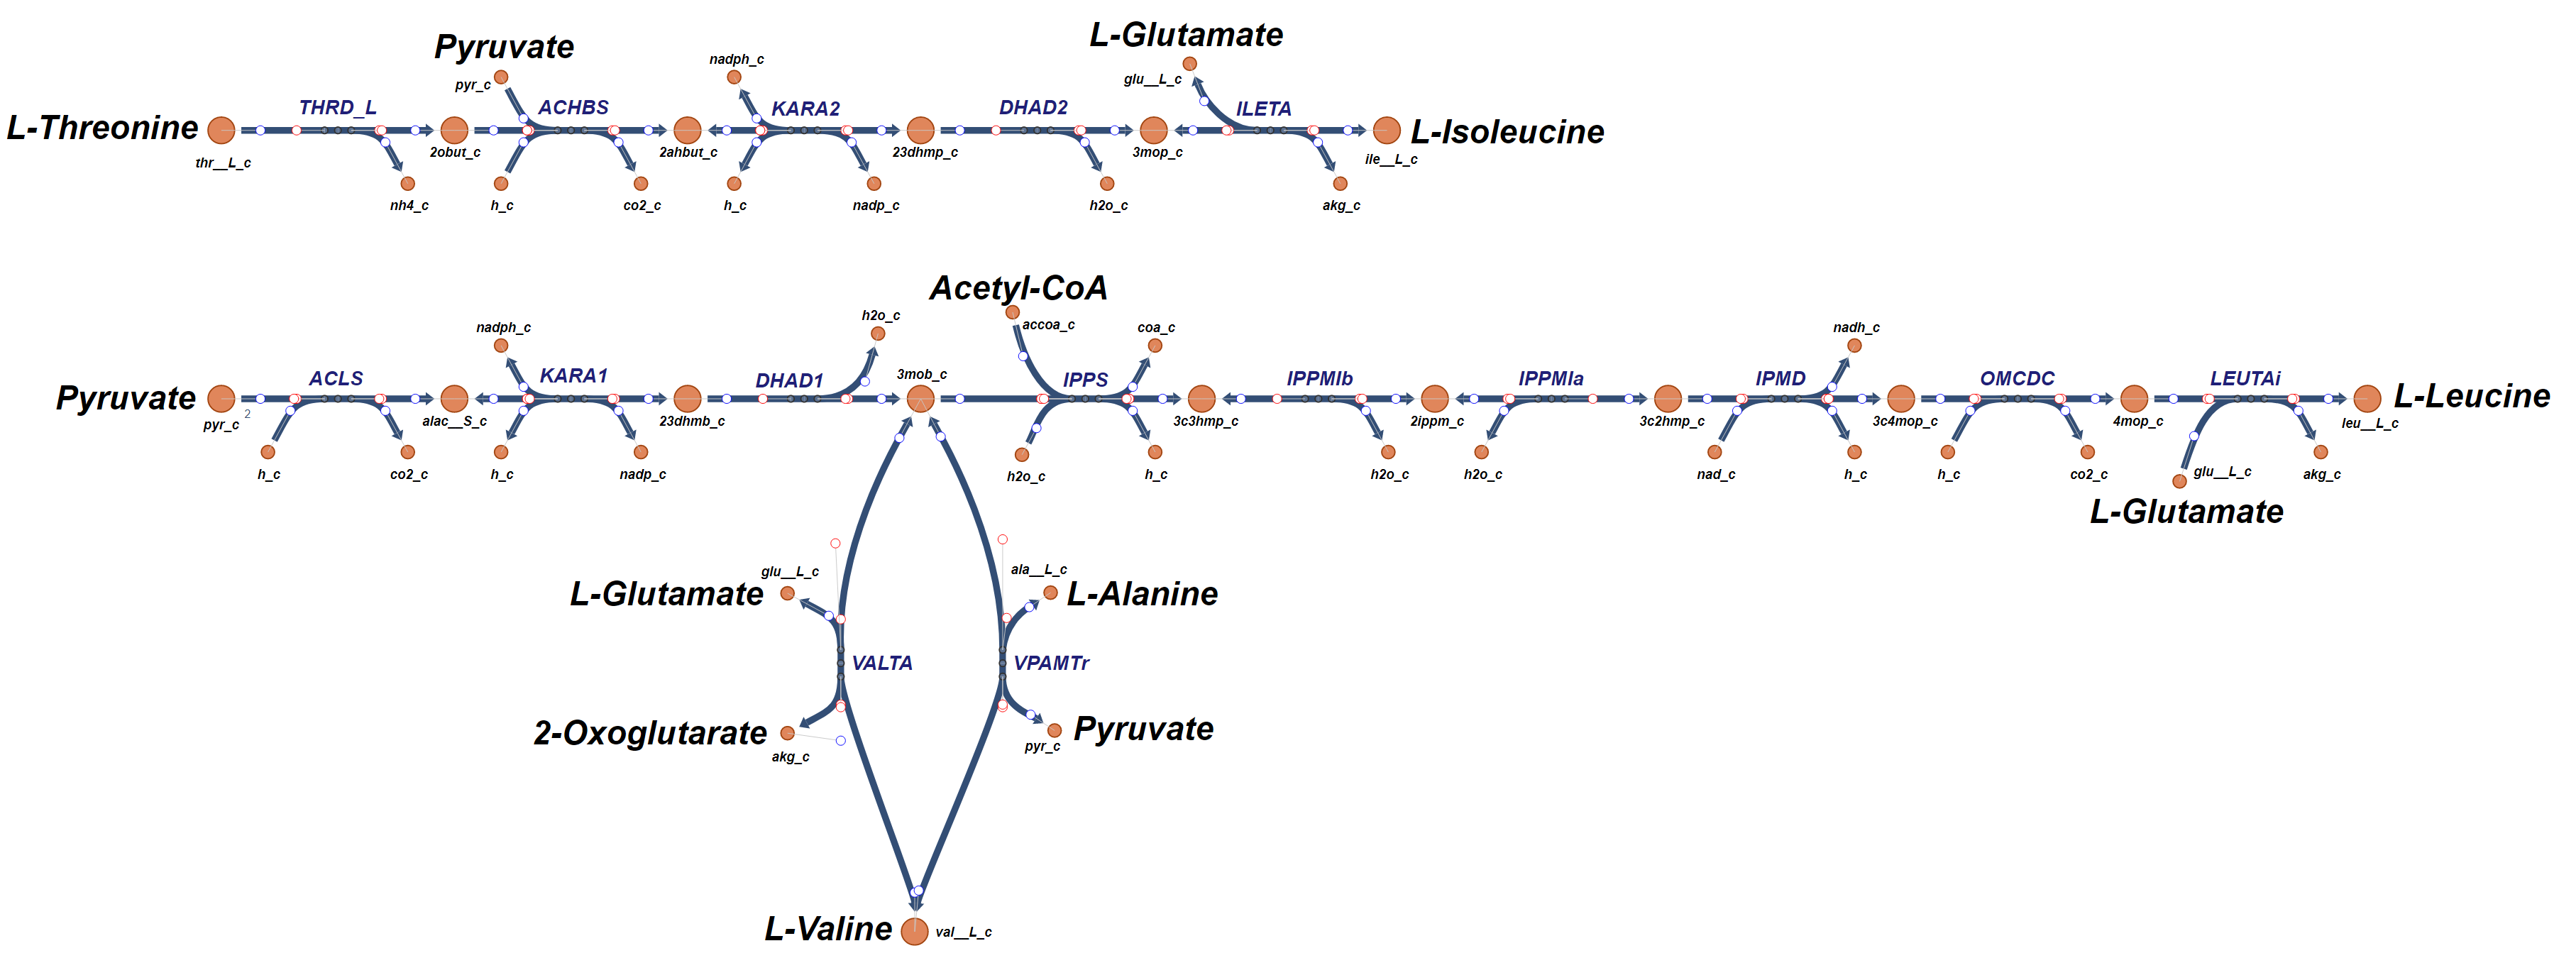

**Figure 1.** The reactions and pathways associated with the "Valine, Leucine, and Isoleucine Metabolism" subsystem.

The  "Valine, Leucine, and Isoleucine Metabolism" conatins pathwasy for the biosynthesis and production of L-Valine, L-Leucine, and L-Isoleucine. The shortest of these pathways is for the production of L-Valine. There are five reactions involved in the primary production pathway of L-Valine;  'ACLS', 'KARA1', 'DHAD1', 'VALTA' and 'VPAMTr'. The pathways begins with the precursor Pyruvate, pass through three reaction ('ACLS', 'KARA1', 'DHAD1') and then obtains its amino group from ether L-Glutatmate ( 'VALTA' ) in an aerobic environment (Valine_Leucine_Isoleucine_Metabolism_Subsystem_Aerobic.png) or L-Alanine ('VPAMTr') under anaerobic conditions (Valine_Leucine_Isoleucine_Metabolism_Subsystem_Anaerobic.png).

The biosynthesis pathway for L-Leucine invovles the first three reactions ('ACLS', 'KARA1', 'DHAD1') required for the L-Valine production in addition to six other reactions, including 'IPPS', 'IPPMIb', 'IPPMIa', 'IPMD', 'OMCDC' and 'LEUTAi'. This pathway requires the precursors Pyruvate and Acetyl-CoA in addition to the amino acid L-Glutamate which provides L-Leucine's amino group. 

The biosynthesis pathway for L-Isoleucine begins with the amino acid L-Threonine and then followed with five reactions, including 'THRD', 'ACHBS', 'KARA2', 'DHAD2', and 'ILETA'. This pathway also requires the precursor Pyruvate in addition to the amino acid L-Glutamate to provide L-Leucine's amino group. 

Now let's begin exploring the biosynthesis pathways for L-Valine, L-Leucine, and L-Isoleucine.

## **3. L-Valine Biosynthesis**

The chemical structure for L-Valine (${\mathrm{C}}_5 {\mathrm{H}}_{11} {\text{NO}}_2$) is shown below. 

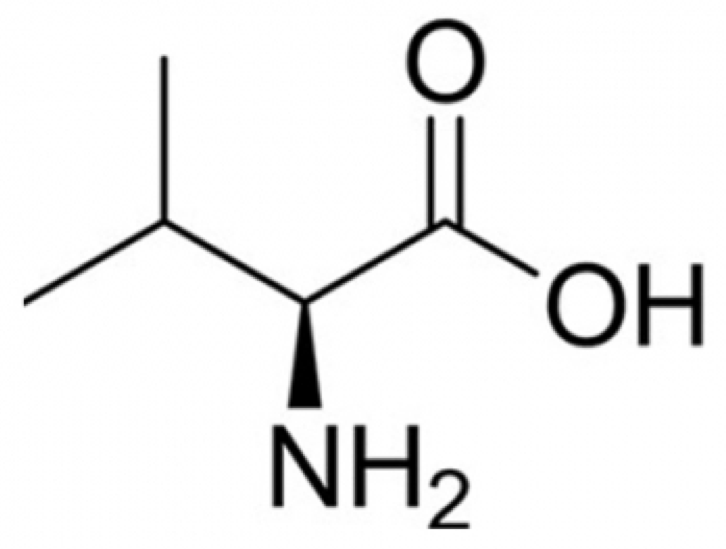

**Figure 2**. The chemical structure of L-Valine(${\mathrm{C}}_5 {\mathrm{H}}_{11} {\text{NO}}_2$) - Wikipedia

L-Valine is a  is hydrophobic amino acid.

## 3.1. L-Valine Biosynthesis Pathways

According to the "Valine and Leucine Metabolism" subsystem there are five reactions invovled in the primary production pathway of L-Valine;  'ACLS', 'KARA1', 'DHAD1', 'VALTA' and 'VPAMTr'. The pathways begins with the precursor Pyruvate, pass through three reaction ('ACLS', 'KARA1', 'DHAD1') and then obtains its amino group from ether L-Glutatmate ( 'VALTA' ) or L-Alanine ('VPAMTr').  To explore the posssibility of other L-Valine production pathways we can use the sufNet function we can identify all the reactions that can directly produce L-Valine.

surfNet(model, 'val__L_c')


Met #1026  val__L_c, L-Valine, C5H11NO2

Consuming reactions:
  #7  BIOMASS_Ec_iJO1366_WT_53p95M, Bd: -0 / -0, E. coli biomass objective function (iJO1366) - WT - with 53.95 GAM estimate
0.000223 10fthf_c + 0.000223 2dmmql8_c + 2.5e-05 2fe2s_c + 0.000248 4fe4s_c + 0.000223 5mthf_c + 
  0.000279 accoa_c + 0.000223 adocbl_c + 0.49915 ala__L_c 

By looking at the bottom of this print-out we can see that there are three reactions, when operating in the forward direction, can produce L-Valine; including 'VALabcpp', 'VALt2rpp',  'VPAMTr'. Notice that two of these reactions, 'VALt2rpp' and 'VPAMTr', are reversible which implies that flux can flow in both directions allowing them to be both produces of L-Valine and consumers. By looking at the "Consuming reactions" listed about the "Producing reactions, 'VALTA', is also reversible allowing it to also be L-Valine producers.

We using the Escher tool [3] can now build a represenation of all the reactions and pathways that can lead to the biosynthesis of L-Valine.

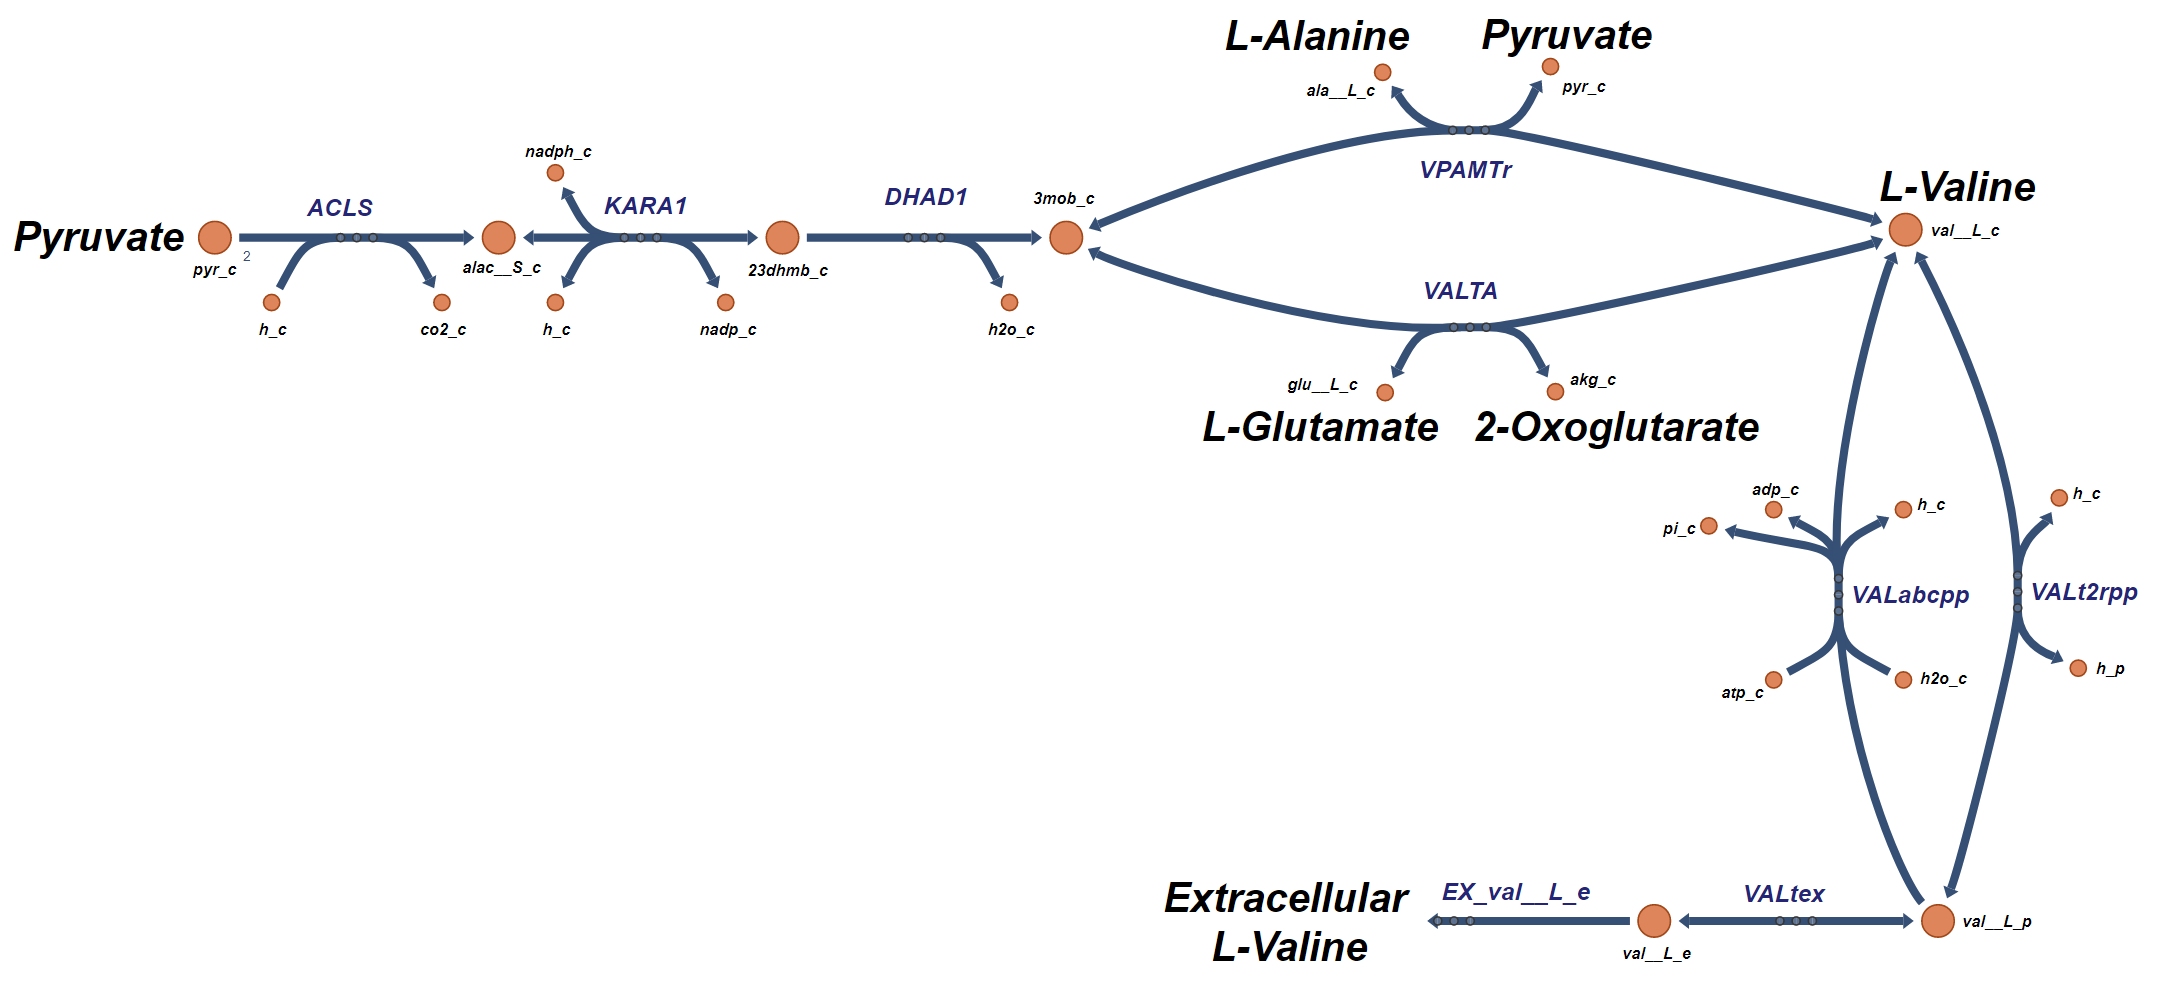

**Figure 3.** Biosynthesis pathways for the production of L-Valine.

From this figure it can be seen that there are only two major pathways that can produce L-Valine. The first is the primary pathway ( 'ACLS', 'KARA1', 'DHAD1', 'VALTA' and 'VPAMTr') and the second is the transporting of L-Valine from the extracellular space (EX_val__L_e', 'VALtex', 'VALabcpp', and 'VALt2rpp'). 

A table showing these reactions, the reaction name and the reaction formula is given below.

ValineReactions = transpose({'ACLS','KARA1','DHAD1','VALTA','VPAMTr',...
    'EX_val__L_e','VALtex','VALabcpp','VALt2rpp'});
[tmp,Valine_rxnID] = ismember(ValineReactions,model.rxns);
reactionNames = model.rxnNames(Valine_rxnID);
reactionFormulas = printRxnFormula(model,ValineReactions,0);
reactionSubsystem = model.subSystems(Valine_rxnID);
% T = table(reactionNames,reactionSubsystem,'RowNames',ValineReactions)
fid = 1;
fprintf(fid,'%-18s %-68s %-50s\r\n','Reaction','Reaction Name','Reaction Formula');

Reaction           Reaction Name                                                        Reaction Formula                                  


[nrows,ncols] = size(ValineReactions);
for row = 1:nrows
    fprintf(fid,'%-18s %-68s %-50s\r\n',ValineReactions{row,:}, reactionNames{row,:}, reactionFormulas{row,:});
end

ACLS               Acetolactate synthase                                                h_c + 2 pyr_c  -> alac__S_c + co2_c               
KARA1              Ketol-acid reductoisomerase (2,3-dihydroxy-3-methylbutanoate)        23dhmb_c + nadp_c  <=> alac__S_c + h_c + nadph_c  
DHAD1              Dihydroxy-acid dehydratase (2,3-dihydroxy-3-methylbutanoate)         23dhmb_c  -> 3mob_c + h2o_c                       
VALTA              Valine transaminase                                                  akg_c + val__L_c  <=> 3mob_c + glu__L_c           
VPAMTr             Valine-pyruvate aminotransferase                                     3mob_c + ala__L_c  <=> pyr_c + val__L_c           
EX_val__L_e        L-Valine exchange                                                    val__L_e  ->                                      
VALtex             L-valine transport via diffusion (extracellular to periplasm)        val__L_e  <=> val__L_p                            
VALabcpp           L-valine

We can also find the subsystems that are associated with each of these reactions.

reactionSubsystems = model.subSystems(Valine_rxnID);
% T = table(reactionNames,reactionSubsystems,'RowNames',ValineReactions)
fid = 1;
fprintf(fid,'%-18s %-50s %-50s\r\n','Reaction','Reaction Name','Reaction Subsystem');

Reaction           Reaction Name                                      Reaction Subsystem                                


[nrows,ncols] = size(ValineReactions);
for row = 1:nrows
    fprintf(fid,'%-18s %-75s %-50s\r\n',ValineReactions{row,:}, reactionNames{row,:}, reactionSubsystems{row,:});
end

ACLS               Acetolactate synthase                                                       Valine, Leucine, and Isoleucine Metabolism        
KARA1              Ketol-acid reductoisomerase (2,3-dihydroxy-3-methylbutanoate)               Valine, Leucine, and Isoleucine Metabolism        
DHAD1              Dihydroxy-acid dehydratase (2,3-dihydroxy-3-methylbutanoate)                Valine, Leucine, and Isoleucine Metabolism        
VALTA              Valine transaminase                                                         Valine, Leucine, and Isoleucine Metabolism        
VPAMTr             Valine-pyruvate aminotransferase                                            Valine, Leucine, and Isoleucine Metabolism        
EX_val__L_e        L-Valine exchange                                                                                                             
VALtex             L-valine transport via diffusion (extracellular to periplasm)               Transport, Outer Membrane Por

## 3.2 L-Valine Aerobic and Anaerobic Operation

Now let's explore the flux through these L-Valine pathways under normal aerobic conditions.

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max',0,0); % Perform FBA
printLabeledData(ValineReactions, round(FBAsolution.x(Valine_rxnID),3))

ACLS	0.859	
KARA1	-0.859	
DHAD1	0.859	
VALTA	-0.416	
VPAMTr	0	
EX_val__L_e	0	
VALtex	0	
VALabcpp	-0	
VALt2rpp	0	


This can be seen using an Escher [3] plot with the "Aerobic_Reaction_Flux.csv" data.

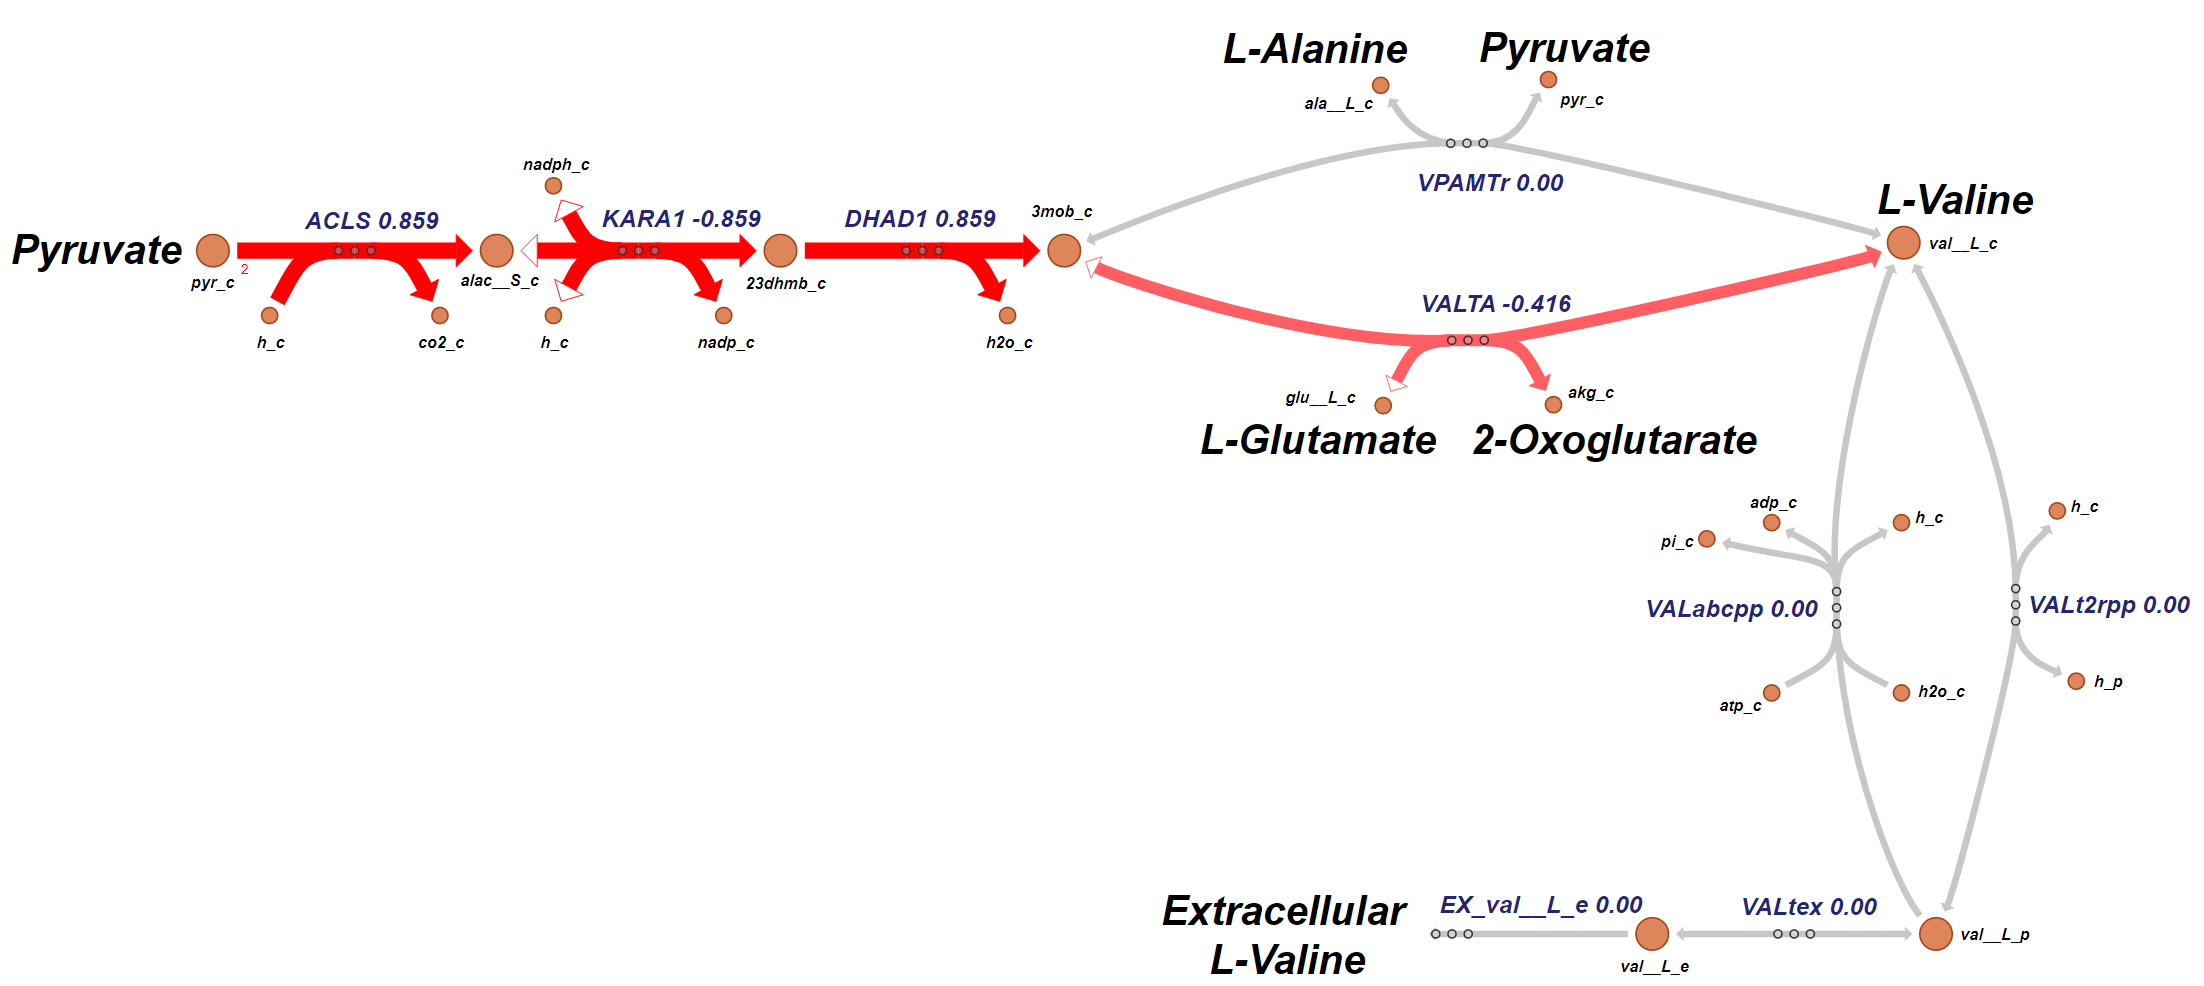

**Figure 4.** L-Valine production under aerobic conditions (Valine_Biosynthesis_Aerobic.png or Valine_Biosynthesis_Aerobic.svg).

It can be seen that all the L-Valine flux is produced through the primary pathway.  

Since there is a difference in the L-Valine pathway under anaerobic conditions lets explore the difference.

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-0,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max',0,0); % Perform FBA
printLabeledData(ValineReactions, round(FBAsolution.x(Valine_rxnID),3))

ACLS	0.211	
KARA1	-0.211	
DHAD1	0.211	
VALTA	-0.243	
VPAMTr	-0.14	
EX_val__L_e	0	
VALtex	0	
VALabcpp	-0	
VALt2rpp	0	


This can be seen using an Escher [3] plot with the "Anaerobic_Reaction_Flux.csv" data.

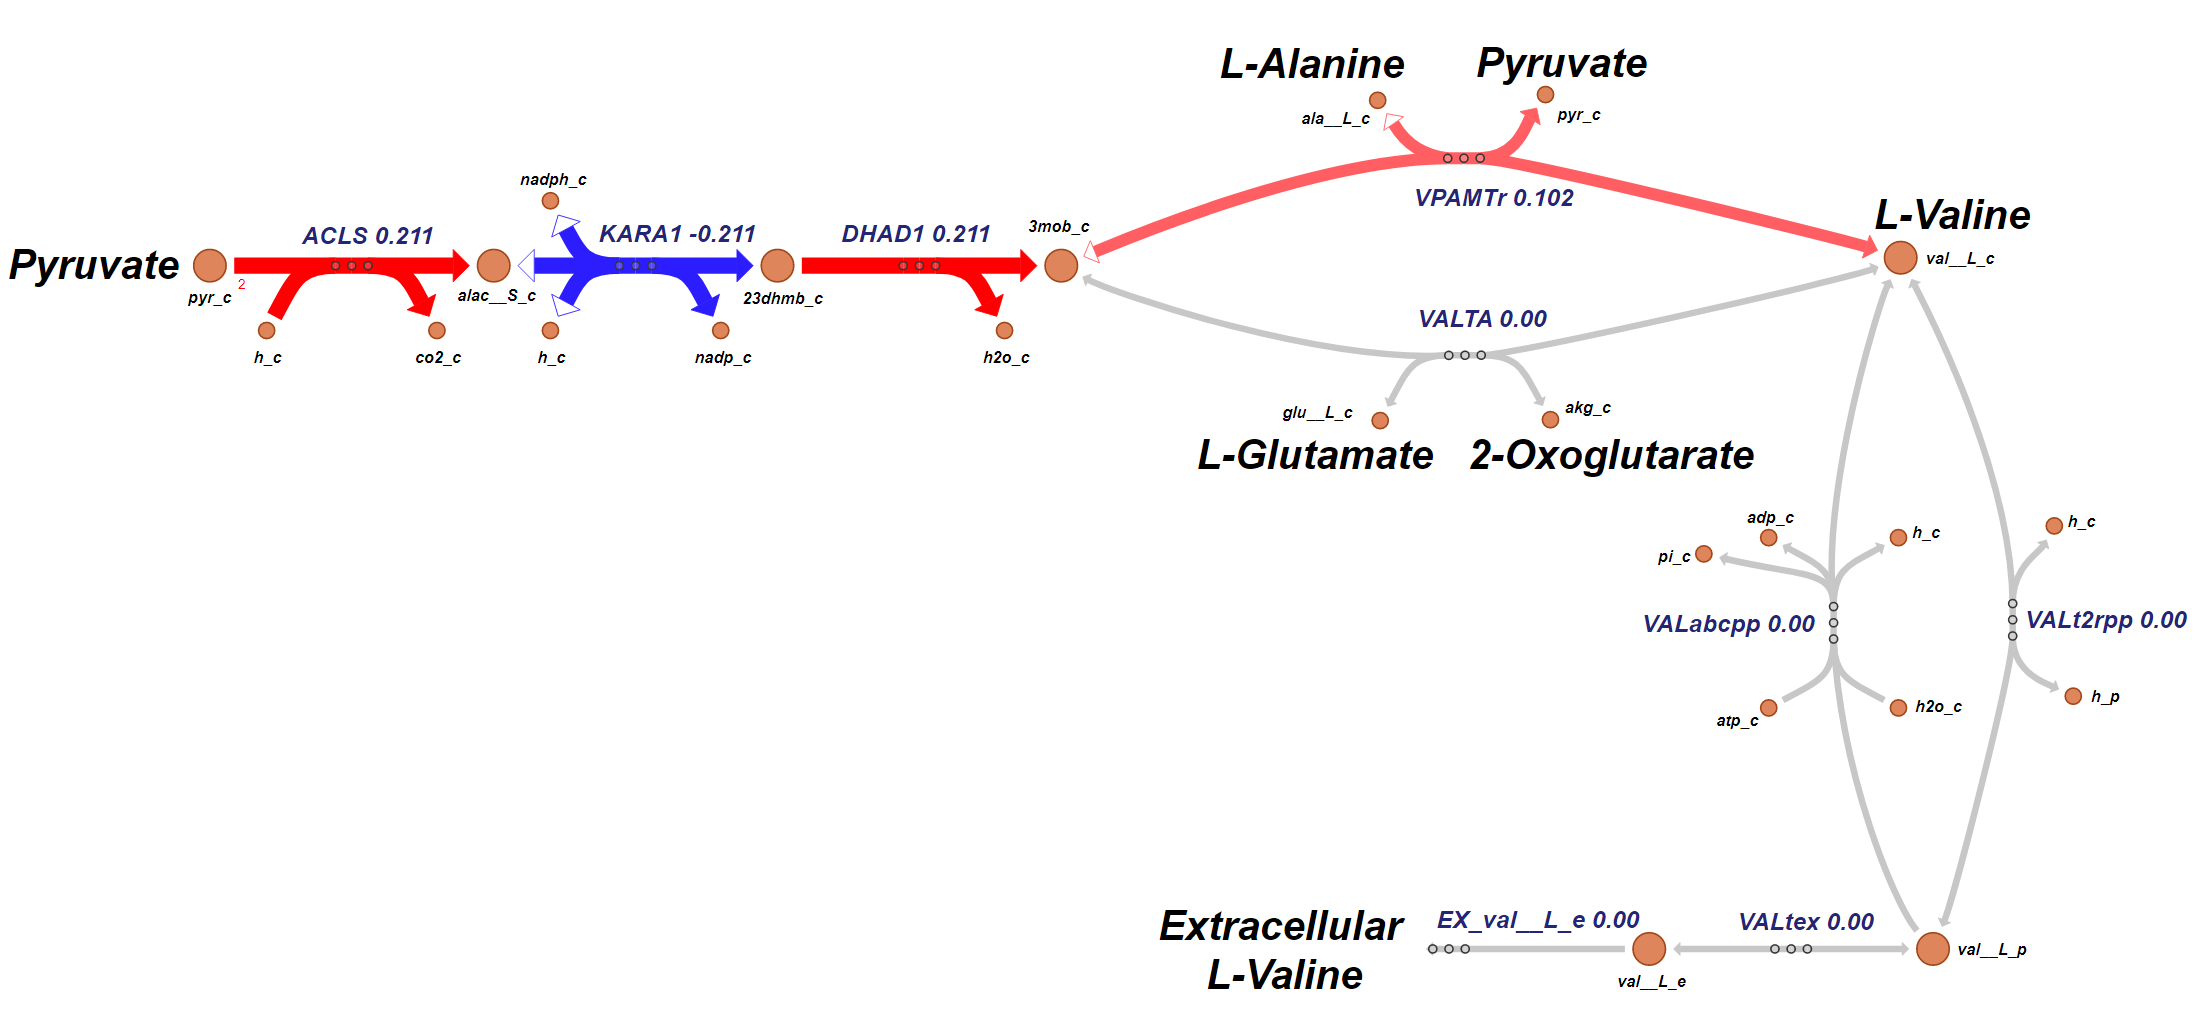

**Figure 5.** L-Valine production under anaerobic conditions (Valine_Biosynthesis_Anaerobic.png or Valine_Biosynthesis_Anaerobic.svg).

Note that the difference in aerobic vs. anaerobic is that the reaction 'VPAMTr' replaces the reaction 'VALTA'.

## 3.3 Excess L-Valine Production

When a cell is producing a recombinant protein, it might be required to produce additional L-Valine for the desired bioproduct.  What is the maximum amount of excess L-Valine, beyond what the cell needs for normal growth, that can be produced for a given growth-rate?

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max'); % Perform FBA to find optimal growth-rate
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',FBAsolution.f,'b'); % Set fixed growth-rate
model = addDemandReaction(model, 'val__L_c');

DM_val__L_c	val__L_c 	->	


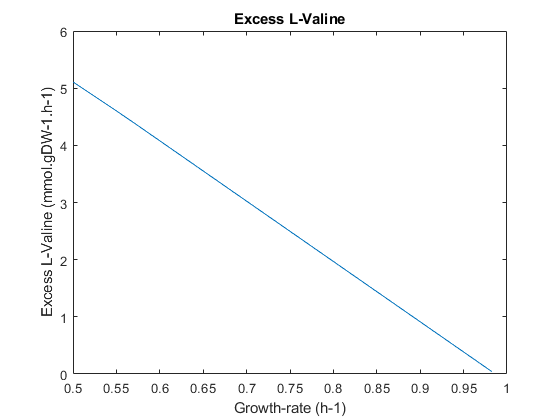

[tmp,Valine_MAX_rxnID] = ismember({'DM_val__L_c'},model.rxns);
model = changeObjective(model,'DM_val__L_c'); % Set the objective function
FBAsolution_Valine = optimizeCbModel(model,'max'); % Perform FBA to find optimal growth-rate
xMin = 0.5;
xMax = FBAsolution.f;
xInc = (xMax - xMin)/20;
x = xMin;
excessValine = [];
growthRate = [];
for i = 1:21
    model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',x,'b'); % Set fixed growth-rate  
    FBAsolution_Valine = optimizeCbModel(model,'max'); % Perform FBA
    excessValine(i) = FBAsolution_Valine.f;
    growthRate(i) = x;
    x = x + xInc;
end
plot(growthRate,excessValine)
title('Excess L-Valine'); 
xlabel('Growth-rate (h-1)'); ylabel('Excess L-Valine (mmol.gDW-1.h-1)');

**Figure 5. **A plot showing the maximum amount of L-Valine that can be produced for a given growth-rate.

This figure illustrates that as the need for excess L-Valine increases the growth-rate will need to decrease. In this figure we can see that the excess L-Valine flux can increase from 0.04372$\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ when the cell is at maximum growth-rate to 5.109 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ when it is at 50% of that optimal growth-rate. Finally, to increase the L-Valine flux beyond these levels will require using the pathways that allow for the transport of L-Valine from the extracellular media. 

## **4. L-Leucine Biosynthesis**

The chemical structure for L-Leucine (${\mathrm{C}}_6 {\mathrm{H}}_{13} {\text{NO}}_2$) is shown below. 

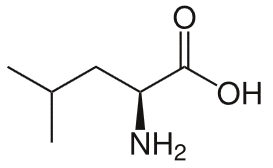

**Figure 2**. The chemical structure of L-Leucine (${\mathrm{C}}_6 {\mathrm{H}}_{13} {\text{NO}}_2$) - Wikipedia

## 4.1.  **L-Leucine** Biosynthesis Pathways

According to the "Valine and Leucine Metabolism" subsytem in Figure 1 there are only pathway that can produce cytoplasmic L-Leucine,  The pathway begins with the precursor Pyruvate and includes the following reactions:  'ACLS', 'KARA1', 'DHAD1', 'IPPS', 'IPPMIb', 'IPPMIa', 'IPMD', 'OMCDC' and 'LEUTAi'. 

To explore the posssibility of other L-Leucine production pathways, we can use the "surfNet" COBRA toolbox function to identify all the reactions that can produce L-Leucine.

surfNet(model, 'leu__L_c')


Met #650  leu__L_c, L-Leucine, C6H13NO2

Consuming reactions:
  #7  BIOMASS_Ec_iJO1366_WT_53p95M, Bd: -0 / -0, E. coli biomass objective function (iJO1366) - WT - with 53.95 GAM estimate
0.000223 10fthf_c + 0.000223 2dmmql8_c + 2.5e-05 2fe2s_c + 0.000248 4fe4s_c + 0.000223 5mthf_c + 
  0.000279 accoa_c + 0.000223 adocbl_c + 0.49915 ala__L_c 

By looking at the bottom of this print-out we can see that there are three reactions, when operating in the forward direction, can produce L-Leucine; including 'LEUTAi', 'LEUabcpp', 'LEULt2rpp'. Notice that only one of these reactions, 'LEULt2rpp', are reversible which implies that flux can flow in both directions allowing them to be both a produces of L-Leucine and a consumer. By looking at the "Consuming reactions" listed above, the "Producing reaction, 'LEUTRS', is irreversible preventing it from become a L-Leucine producers.

We using the Escher tool [3] can now build a represenation of all the reactions and pathways that can lead to the biosynthesis of L-Leucine.

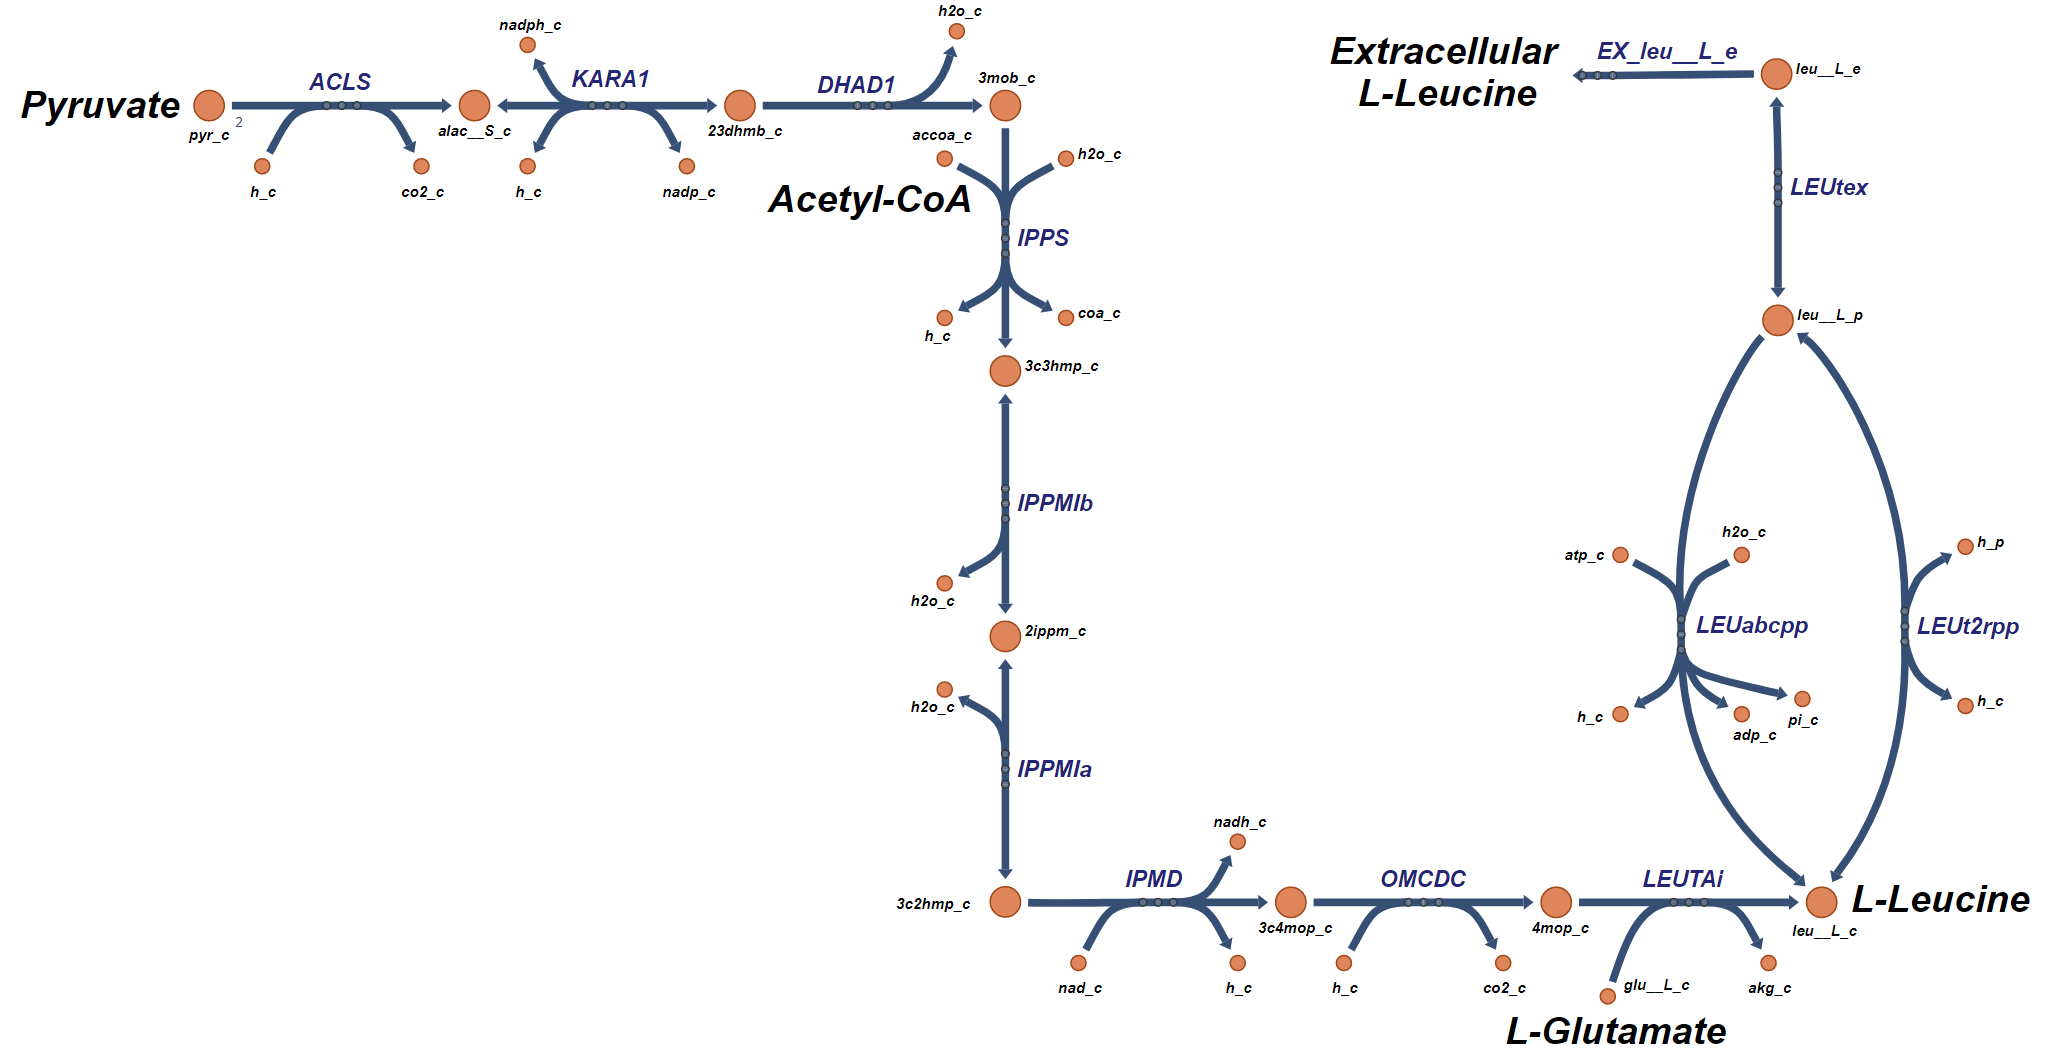

**Figure 6. **Biosynthesis pathways for the production of L-Leucine.

From this figure it can be seen that there are only two major pathways that can produce L-Leucine. The first is the primary pathway ( 'ACLS', 'KARA1', 'DHAD1', 'IPPS', 'IPPMIb', 'IPPMIa', 'IPMD', 'OMCDC' and 'LEUTAi') and the second is the transporting of L-Leucine from the extracellular space ('EX_leu__L_e', 'LEUtex', 'LEUabcpp', and 'LEUt2rpp'). 

A table showing these reactions, the reaction name and the reaction formula is given below.

LeucineReactions = transpose({ 'ACLS','KARA1','DHAD1','IPPS','IPPMIb','IPPMIa','IPMD','OMCDC', 'LEUTAi',...
    'EX_leu__L_e','LEUtex','LEUabcpp','LEUt2rpp'});
[tmp,Leucine_rxnID] = ismember(LeucineReactions,model.rxns);
reactionNames = model.rxnNames(Leucine_rxnID);
reactionFormulas = printRxnFormula(model,LeucineReactions,0);
reactionSubsystem = model.subSystems(Leucine_rxnID);
% T = table(reactionNames,reactionSubsystem,'RowNames',LeucineReactions)
fid = 1;
fprintf(fid,'%-18s %-68s %-50s\r\n','Reaction','Reaction Name','Reaction Formula');

Reaction           Reaction Name                                                        Reaction Formula                                  


[nrows,ncols] = size(LeucineReactions);
for row = 1:nrows
    fprintf(fid,'%-18s %-68s %-50s\r\n',LeucineReactions{row,:}, reactionNames{row,:}, reactionFormulas{row,:});
end

ACLS               Acetolactate synthase                                                h_c + 2 pyr_c  -> alac__S_c + co2_c               
KARA1              Ketol-acid reductoisomerase (2,3-dihydroxy-3-methylbutanoate)        23dhmb_c + nadp_c  <=> alac__S_c + h_c + nadph_c  
DHAD1              Dihydroxy-acid dehydratase (2,3-dihydroxy-3-methylbutanoate)         23dhmb_c  -> 3mob_c + h2o_c                       
IPPS               2-isopropylmalate synthase                                           3mob_c + accoa_c + h2o_c  -> 3c3hmp_c + coa_c + h_c 
IPPMIb             2-isopropylmalate hydratase                                          2ippm_c + h2o_c  <=> 3c3hmp_c                     
IPPMIa             3-isopropylmalate dehydratase                                        3c2hmp_c  <=> 2ippm_c + h2o_c                     
IPMD               3-isopropylmalate dehydrogenase                                      3c2hmp_c + nad_c  -> 3c4mop_c + h_c + nadh_c      
OMCDC              2-Oxo-

We can also find the subsystems that are associated with each of these reactions.

reactionSubsystems = model.subSystems(Leucine_rxnID);
% T = table(reactionNames,reactionSubsystems,'RowNames',LeucineReactions)
fid = 1;
fprintf(fid,'%-18s %-50s %-50s\r\n','Reaction','Reaction Name','Reaction Subsystem');

Reaction           Reaction Name                                      Reaction Subsystem                                


[nrows,ncols] = size(LeucineReactions);
for row = 1:nrows
    fprintf(fid,'%-18s %-75s %-50s\r\n',LeucineReactions{row,:}, reactionNames{row,:}, reactionSubsystems{row,:});
end

ACLS               Acetolactate synthase                                                       Valine, Leucine, and Isoleucine Metabolism        
KARA1              Ketol-acid reductoisomerase (2,3-dihydroxy-3-methylbutanoate)               Valine, Leucine, and Isoleucine Metabolism        
DHAD1              Dihydroxy-acid dehydratase (2,3-dihydroxy-3-methylbutanoate)                Valine, Leucine, and Isoleucine Metabolism        
IPPS               2-isopropylmalate synthase                                                  Valine, Leucine, and Isoleucine Metabolism        
IPPMIb             2-isopropylmalate hydratase                                                 Valine, Leucine, and Isoleucine Metabolism        
IPPMIa             3-isopropylmalate dehydratase                                               Valine, Leucine, and Isoleucine Metabolism        
IPMD               3-isopropylmalate dehydrogenase                                             Valine, Leucine, and Isoleuci

## 4.2. L-Leucine Aerobic Operation

Now let's explore the flux through these L-Leucine pathways under normal aerobic conditions.

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max',0,0); % Perform FBA
printLabeledData(LeucineReactions, round(FBAsolution.x(Leucine_rxnID),3))

ACLS	0.859	
KARA1	-0.859	
DHAD1	0.859	
IPPS	0.443	
IPPMIb	-0.443	
IPPMIa	-0.443	
IPMD	0.443	
OMCDC	0.443	
LEUTAi	0.443	
EX_leu__L_e	0	
LEUtex	0	
LEUabcpp	0	
LEUt2rpp	0	


This can be visualized using an Escher [3] plot with the "Aerobic_Reaction_Flux.csv" data.

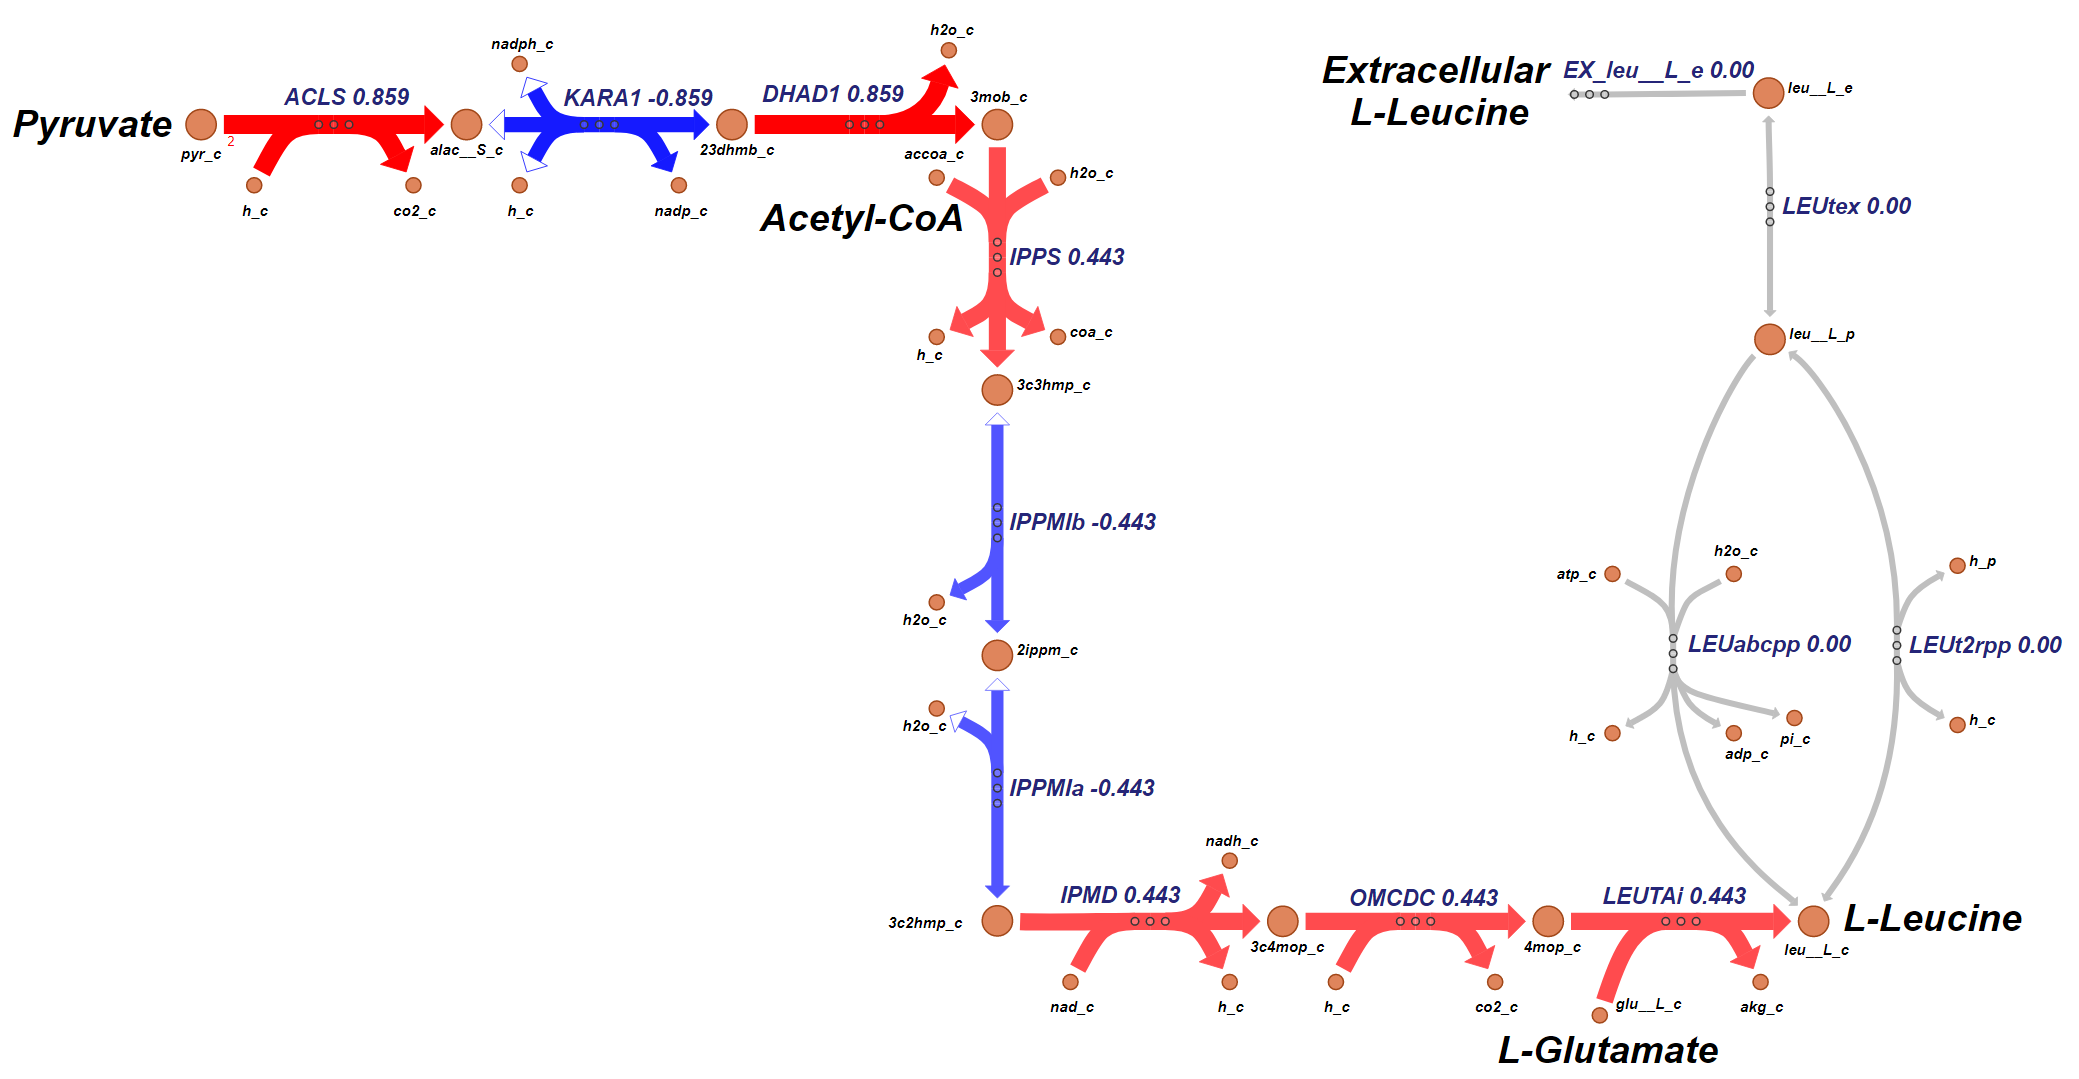

**Figure 6. **Aerobic production of L-Leucine (Leucine_Biosynthesis_Aerobic.png or Leucine_Biosynthesis_Aerobic.svg).

This figure shows the L-Leucine flux supported by the primary pathway.  

## 4.3 Excess L-Leucine Production

When a cell is producing a recombinant protein, it might be required to produce additional L-Leucine for the desired bioproduct.  What is the maximum amount of excess L-Leucine, beyond what the cell needs for normal growth, that can be produced for a given growth-rate?

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max'); % Perform FBA to find optimal growth-rate
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',FBAsolution.f,'b'); % Set fixed growth-rate
model = addDemandReaction(model, 'leu__L_c');

DM_leu__L_c	leu__L_c 	->	


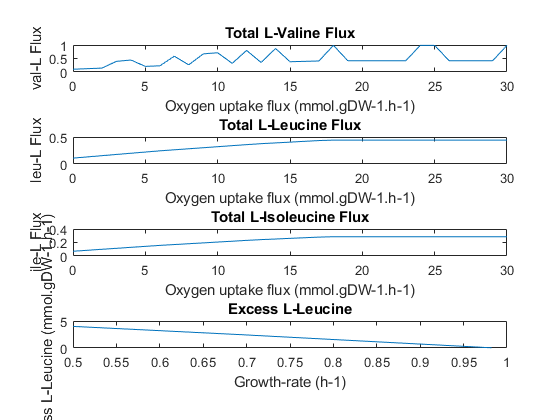

[tmp,Valine_MAX_rxnID] = ismember({'DM_leu__L_c'},model.rxns);
model = changeObjective(model,'DM_leu__L_c'); % Set the objective function
FBAsolution_Leucine = optimizeCbModel(model,'max'); % Perform FBA to find optimal growth-rate
xMin = 0.5;
xMax = FBAsolution.f;
xInc = (xMax - xMin)/20;
x = xMin;
excessLeucine = [];
growthRate = [];
for i = 1:21
    model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',x,'b'); % Set fixed growth-rate  
    FBAsolution_Leucine = optimizeCbModel(model,'max'); % Perform FBA
    excessLeucine(i) = FBAsolution_Leucine.f;
    growthRate(i) = x;
    x = x + xInc;
end
plot(growthRate,excessLeucine)
title('Excess L-Leucine'); 
xlabel('Growth-rate (h-1)'); ylabel('Excess L-Leucine (mmol.gDW-1.h-1)');

**Figure 5. **A plot showing the maximum amount of L-Leucine that can be produced for a given growth-rate.

This figure illustrates that as the need for excess L-Leucine increases the growth-rate will need to decrease. In this figure we can see that the excess L-Leucine flux can increase from 0.0349 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ when the cell is at maximum growth-rate to 4.003 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ when it is at 50% of that optimal growth-rate. Finally, to increase the L-Leucine flux beyond these levels will require using the pathways that allow for the transport of L-Leucine from the extracellular media. 

## **4. L-Isoleucine Biosynthesis**

The chemical structure for L-Isoleucine (${\mathrm{C}}_6 {\mathrm{H}}_{13} {\text{NO}}_2$) is shown below. 

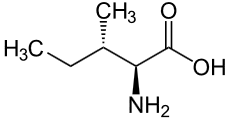

**Figure 2**. The chemical structure of L-Isoleucine (${\mathrm{C}}_6 {\mathrm{H}}_{13} {\text{NO}}_2$) - Wikipedia

## 4.1.  **L-Isoleucine** Biosynthesis Pathways

According to the "Valine and Leucine Metabolism" subsytem in Figure 1 there are only pathway that can produce cytoplasmic L-Isoleucine,  The pathway begins with the amino acid L-Threonine and includes the following reactions:  'THRD_L', 'ACHBS', 'KARA2', 'DHAD2', and 'ILETA'.

To explore the posssibility of other L-Valine production pathways we can use the "sufNet" function to identify all the reactions that can produce L-Isoleucine.

surfNet(model, 'ile__L_c')


Met #621  ile__L_c, L-Isoleucine, C6H13NO2

Consuming reactions:
  #7  BIOMASS_Ec_iJO1366_WT_53p95M, Bd: 0.98237 / 0.98237, E. coli biomass objective function (iJO1366) - WT - with 53.95 GAM estimate
0.000223 10fthf_c + 0.000223 2dmmql8_c + 2.5e-05 2fe2s_c + 0.000248 4fe4s_c + 0.000223 5mthf_c + 
  0.000279 accoa_c + 0.000223 adocbl_c + 0.49915 

From these results we can see that there are two reactions that can directly produce cytoplasmic L-Isoleucine in the forward direction, they include  'ILEabcpp' and 'ILEt2rpp'. Notice that only one of these reactions, 'ILELt2rpp', are reversible which implies that flux can flow in both directions allowing them to be both a produces of L-Isoleucine and a consumer. By looking at the "Consuming reactions" listed above, the "Producing reaction, 'ILETA', allowing it to be an L-Isoleucine producer. 

We using the Escher tool [3] can now build a represenation of all the reactions and pathways that can lead to the biosynthesis of L-Isoleucine.

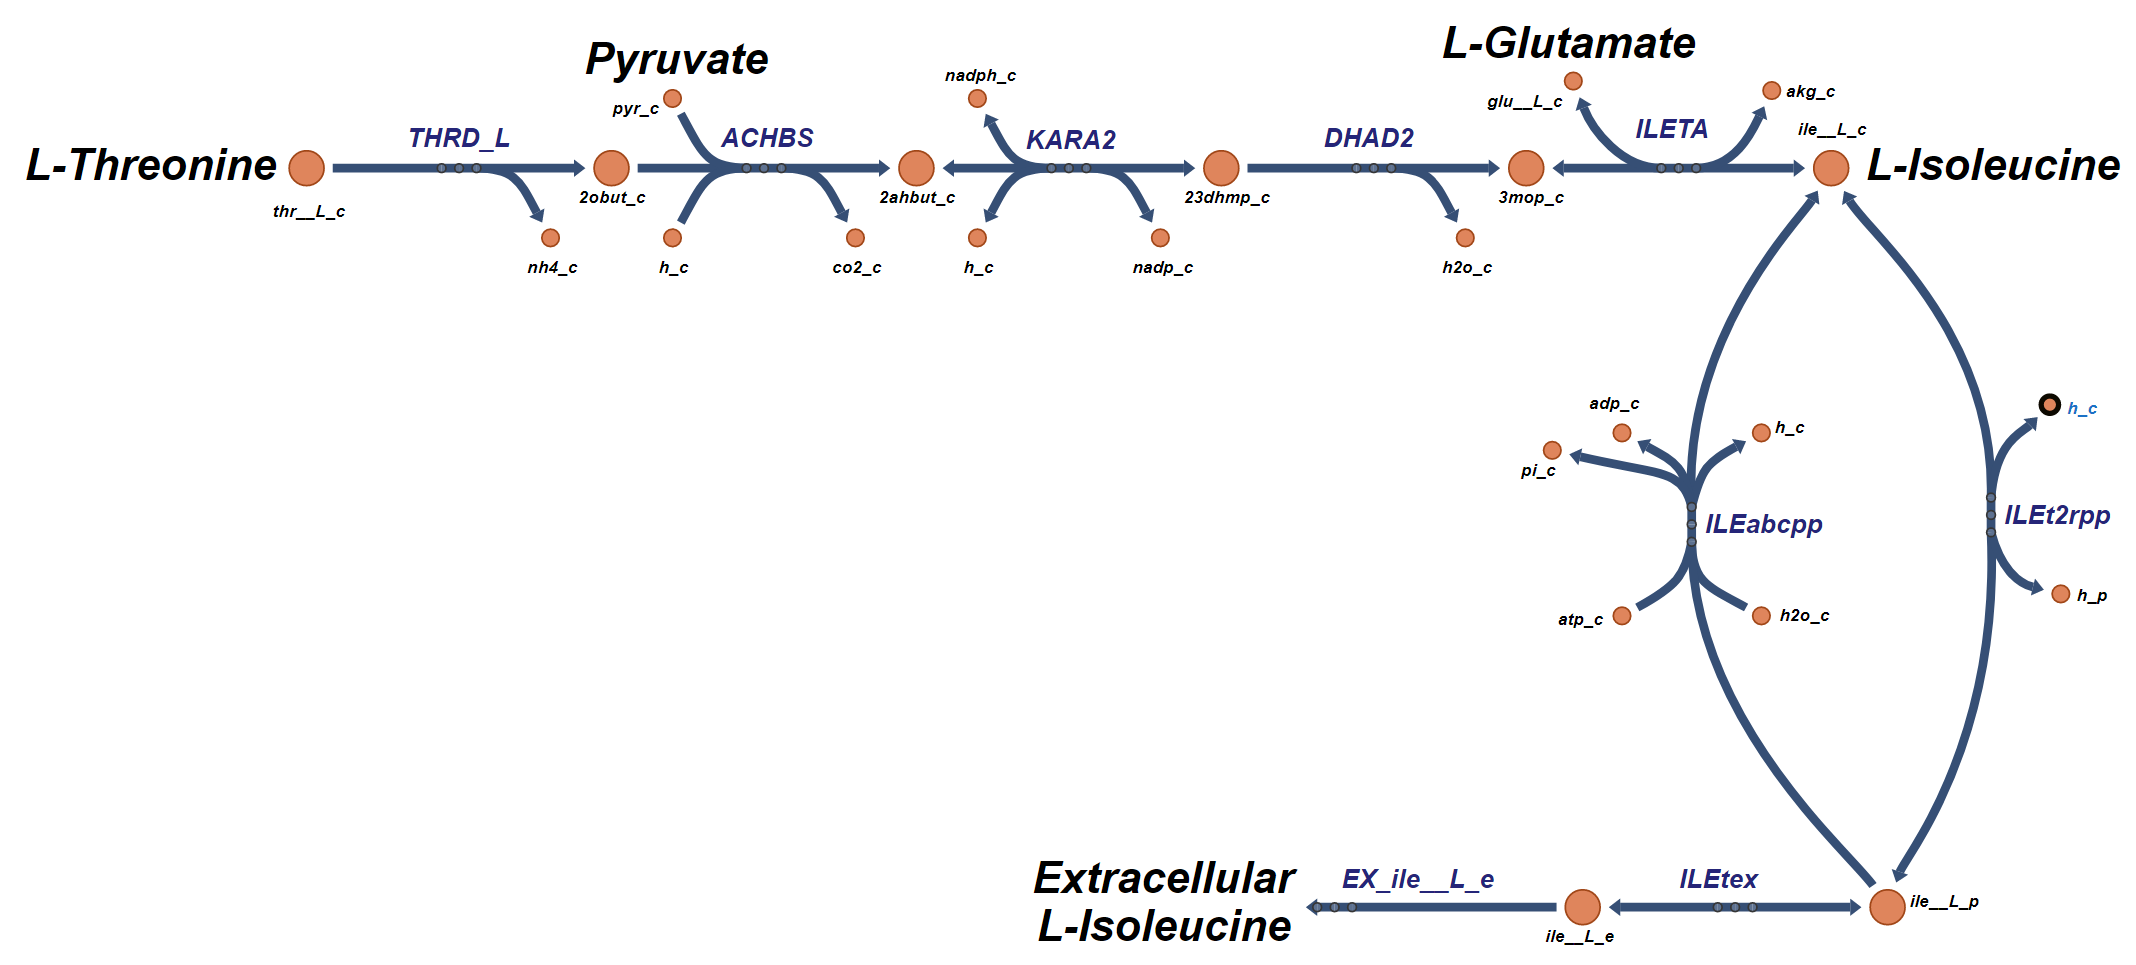

**Figure 6. **Biosynthesis pathways for the production of L-Isoleucine (Isoleucine_Biosynthesis.json, Isoleucine_Biosynthesis.png or Isoleucine_Biosynthesis.svg).

From this figure it can be seen that there are only two major pathways that can produce L-Leucine. The first is the primary pathway ( 'ACLS', 'KARA1', 'DHAD1', 'IPPS', 'IPPMIb', 'IPPMIa', 'IPMD', 'OMCDC' and 'LEUTAi') and the second is the transporting of L-Leucine from the extracellular space ('EX_leu__L_e', 'LEUtex', 'LEUabcpp', and 'LEUt2rpp'). 

A table showing these reactions, the reaction name and the reaction formula is given below.

IsoleucineReactions = transpose({ 'ACLS','KARA1','DHAD1','IPPS','IPPMIb','IPPMIa','IPMD','OMCDC','LEUTAi',...
    'EX_leu__L_e','LEUtex','LEUabcpp','LEUt2rpp'});
[tmp,Isoleucine_rxnID] = ismember(IsoleucineReactions,model.rxns);
reactionNames = model.rxnNames(Isoleucine_rxnID);
reactionFormulas = printRxnFormula(model,IsoleucineReactions,0);
reactionSubsystem = model.subSystems(Isoleucine_rxnID);
% T = table(reactionNames,reactionSubsystem,'RowNames',IsoleucineReactions)
fid = 1;
fprintf(fid,'%-18s %-68s %-50s\r\n','Reaction','Reaction Name','Reaction Formula');

Reaction           Reaction Name                                                        Reaction Formula                                  


[nrows,ncols] = size(IsoleucineReactions);
for row = 1:nrows
    fprintf(fid,'%-18s %-68s %-50s\r\n',IsoleucineReactions{row,:}, reactionNames{row,:}, reactionFormulas{row,:});
end

ACLS               Acetolactate synthase                                                h_c + 2 pyr_c  -> alac__S_c + co2_c               
KARA1              Ketol-acid reductoisomerase (2,3-dihydroxy-3-methylbutanoate)        23dhmb_c + nadp_c  <=> alac__S_c + h_c + nadph_c  
DHAD1              Dihydroxy-acid dehydratase (2,3-dihydroxy-3-methylbutanoate)         23dhmb_c  -> 3mob_c + h2o_c                       
IPPS               2-isopropylmalate synthase                                           3mob_c + accoa_c + h2o_c  -> 3c3hmp_c + coa_c + h_c 
IPPMIb             2-isopropylmalate hydratase                                          2ippm_c + h2o_c  <=> 3c3hmp_c                     
IPPMIa             3-isopropylmalate dehydratase                                        3c2hmp_c  <=> 2ippm_c + h2o_c                     
IPMD               3-isopropylmalate dehydrogenase                                      3c2hmp_c + nad_c  -> 3c4mop_c + h_c + nadh_c      
OMCDC              2-Oxo-

We can also find the subsystems that are associated with each of these reactions.

reactionSubsystems = model.subSystems(Isoleucine_rxnID);
% T = table(reactionNames,reactionSubsystems,'RowNames',IsoleucineReactions)
fid = 1;
fprintf(fid,'%-18s %-50s %-50s\r\n','Reaction','Reaction Name','Reaction Subsystem');

Reaction           Reaction Name                                      Reaction Subsystem                                


[nrows,ncols] = size(IsoleucineReactions);
for row = 1:nrows
    fprintf(fid,'%-18s %-75s %-50s\r\n',IsoleucineReactions{row,:}, reactionNames{row,:}, reactionSubsystems{row,:});
end

ACLS               Acetolactate synthase                                                       Valine, Leucine, and Isoleucine Metabolism        
KARA1              Ketol-acid reductoisomerase (2,3-dihydroxy-3-methylbutanoate)               Valine, Leucine, and Isoleucine Metabolism        
DHAD1              Dihydroxy-acid dehydratase (2,3-dihydroxy-3-methylbutanoate)                Valine, Leucine, and Isoleucine Metabolism        
IPPS               2-isopropylmalate synthase                                                  Valine, Leucine, and Isoleucine Metabolism        
IPPMIb             2-isopropylmalate hydratase                                                 Valine, Leucine, and Isoleucine Metabolism        
IPPMIa             3-isopropylmalate dehydratase                                               Valine, Leucine, and Isoleucine Metabolism        
IPMD               3-isopropylmalate dehydrogenase                                             Valine, Leucine, and Isoleuci

## 5.2. L-Isoleucine Aerobic Operation

Now let's explore the flux through these L-Isoleucine pathways under normal aerobic conditions.

model = saved_model;
IsoleucineReactions = transpose({'ASPTA','ASNS1','ASNS2','EX_asp__L_e','ASPtex','ASPabcpp','ASPt2_2pp',...
    'ASPt2_3pp','ASPt2pp_copy1','ASPt2pp_copy2','SUCASPtpp','EX_asn__L_e','ASNtex','ASNNpp','ASNabcpp',...
    'ASNt2rpp','ASPK'});
[tmp,Isoleucine_rxnID] = ismember(IsoleucineReactions,model.rxns);
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max',0,0); % Perform FBA
printLabeledData(IsoleucineReactions, round(FBAsolution.x(Isoleucine_rxnID),3))

ASPTA	-2.876	
ASNS1	0	
ASNS2	0.237	
EX_asp__L_e	0	
ASPtex	0	
ASPabcpp	0	
ASPt2_2pp	0	
ASPt2_3pp	0	
ASPt2pp_copy1	0	
ASPt2pp_copy2	0	
SUCASPtpp	0	
EX_asn__L_e	0	
ASNtex	0	
ASNNpp	0	
ASNabcpp	-0	
ASNt2rpp	0	
ASPK	1.05	


This can be visualized using an Escher [3] plot with the "Aerobic_Reaction_Flux.csv" data.

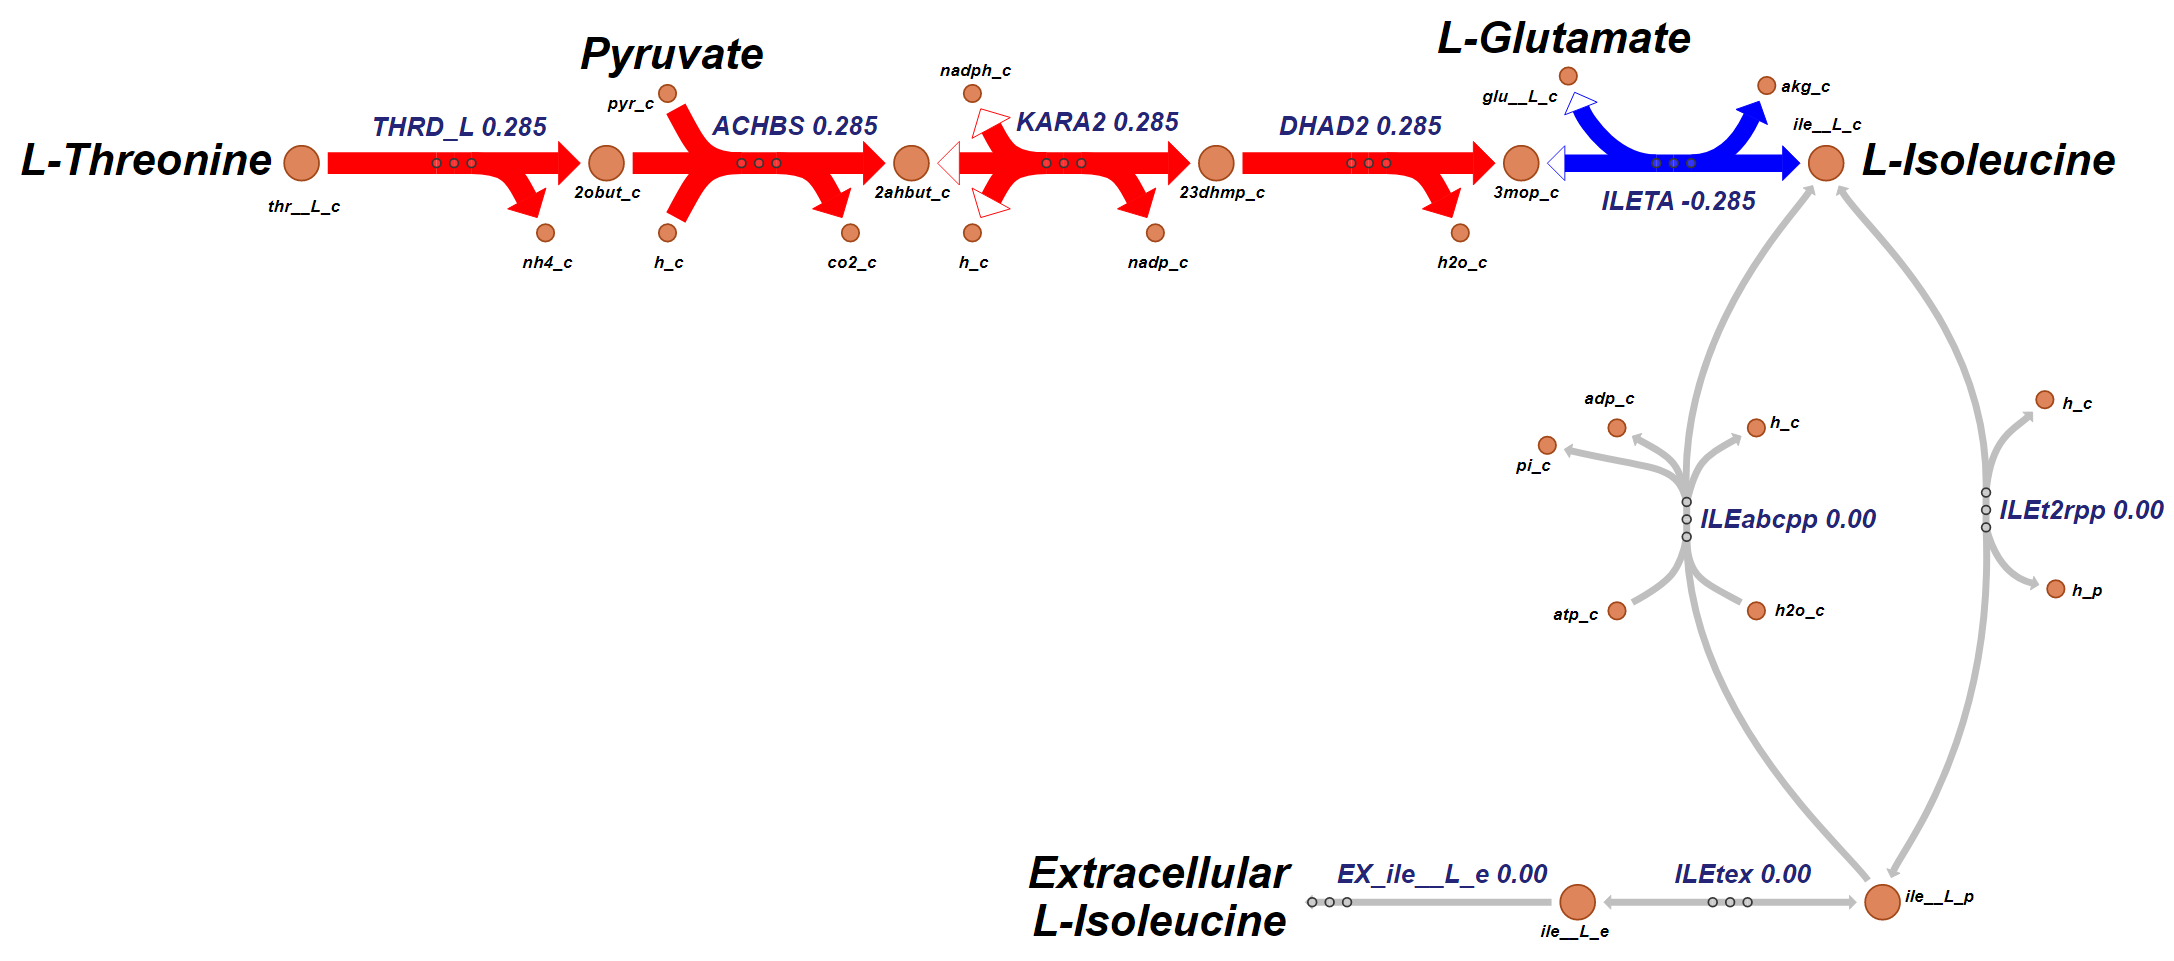

**Figure 7. **Aerobic production of L-Isoeucine (Isoleucine_Biosynthesis_Aerobic.png or Isoleucine_Biosynthesis_Aerobic.svg).

This figure shows the L-Leucine flux supported by the primary pathway.  

## 4.3 Excess L-Isoleucine Production

When a cell is producing a recombinant protein, it might be required to produce additional L-Isoleucine for the desired bioproduct.  What is the maximum amount of excess L-Isoleucine, beyond what the cell needs for normal growth, that can be produced for a given growth-rate?

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max'); % Perform FBA to find optimal growth-rate
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',FBAsolution.f,'b'); % Set fixed growth-rate
model = addDemandReaction(model, 'ile__L_c');

DM_ile__L_c	ile__L_c 	->	


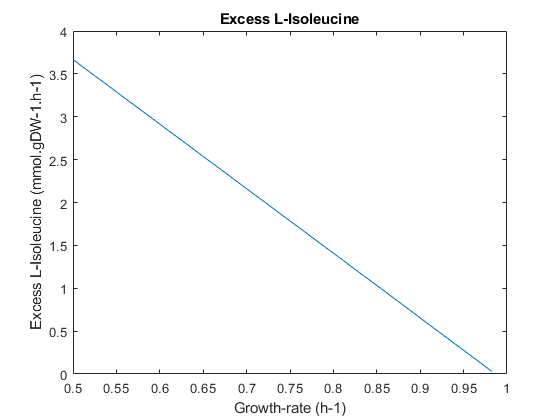

[tmp,Isoleucine_MAX_rxnID] = ismember({'DM_ile__L_c'},model.rxns);
model = changeObjective(model,'DM_ile__L_c'); % Set the objective function
FBAsolution_Isoleucine = optimizeCbModel(model,'max'); % Perform FBA to find optimal growth-rate
xMin = 0.5;
xMax = FBAsolution.f;
xInc = (xMax - xMin)/20;
x = xMin;
excessIsoleucine = [];
growthRate = [];
for i = 1:21
    model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',x,'b'); % Set fixed growth-rate  
    FBAsolution_Isoleucine = optimizeCbModel(model,'max'); % Perform FBA
    excessIsoleucine(i) = FBAsolution_Isoleucine.f;
    growthRate(i) = x;
    x = x + xInc;
end
plot(growthRate,excessIsoleucine)
title('Excess L-Isoleucine'); 
xlabel('Growth-rate (h-1)'); ylabel('Excess L-Isoleucine (mmol.gDW-1.h-1)');

**Figure 5. **A plot showing the maximum amount of L-Isoleucine that can be produced for a given growth-rate.

This figure illustrates that as the need for excess L-Isoleucine increases the growth-rate will need to decrease. In this figure we can see that the excess L-Isoleucine flux can increase from 0.03133 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ when the cell is at maximum growth-rate to 3.667 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ when it is at 50% of that optimal growth-rate. Finally, to increase the L-Isoleucine flux beyond these levels will require using the pathways that allow for the transport of L-Isoleucine from the extracellular media. 

## 5. Aerobic vs Anaerobic Amino Acid Production

Now let's look at the total amount of flux that is created for each of these amino acids as the oxygen content varies from anerobic to aerobic.

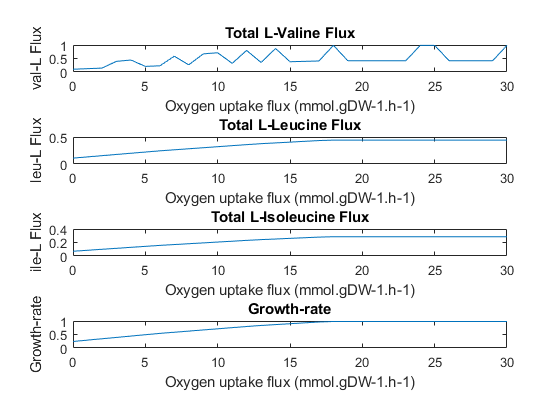

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
val_flux = [];
leu_flux = [];
ile_flux = [];
for k = 1:31
    model = changeRxnBounds(model,'EX_o2_e',-(k-1),'b'); % Set oxygen uptake
    FBAsolution = optimizeCbModel(model,'max',0,0); % Perform FBA
    [P, C, vP, vC] = computeFluxSplits(model, {'val__L_c'}, FBAsolution.x);
    val_flux(k) = sum(vP);
    [P, C, vP, vC] = computeFluxSplits(model, {'leu__L_c'}, FBAsolution.x);
    leu_flux(k) = sum(vP);
    [P, C, vP, vC] = computeFluxSplits(model, {'ile__L_c'}, FBAsolution.x);
    ile_flux(k) = sum(vP);    
    growthRate(k) = FBAsolution.f;
end

figure(1)
oFlux = 0:30;
ax1 = subplot(4,1,1); % top subplot
ax2 = subplot(4,1,2); % middle subplot
ax3 = subplot(4,1,3); % bottom subplot
ax4 = subplot(4,1,4); % bottom subplot

plot(ax1,oFlux,val_flux)
title(ax1,'Total L-Valine Flux'); 
xlabel(ax1,'Oxygen uptake flux (mmol.gDW-1.h-1)'); ylabel(ax1,'val-L Flux');

plot(ax2,oFlux,leu_flux);
title(ax2,'Total L-Leucine Flux'); 
xlabel(ax2,'Oxygen uptake flux (mmol.gDW-1.h-1)'); ylabel(ax2,'leu-L Flux'); 

plot(ax3,oFlux,ile_flux);
title(ax3,'Total L-Isoleucine Flux'); 
xlabel(ax3,'Oxygen uptake flux (mmol.gDW-1.h-1)'); ylabel(ax3,'ile-L Flux'); 

plot(ax4,oFlux,growthRate);
title(ax4,'Growth-rate'); 
xlabel(ax4,'Oxygen uptake flux (mmol.gDW-1.h-1)'); ylabel(ax4,'Growth-rate'); 

**Figure 9.** A plot showing the total amount of flux that is can be created for each of these amino acids as the oxygen content varies from anerobic to aerobic.

Note that the noise on the L-Valine chart is the result of loops in the production pathways. 

## 6. Conclusion

The purpose of this tutorial was to identify and review the structure and capabilities of the "Valine and Leucine Metabolism" subsystem of the *E.coli* iJO1366 model. It began with an overview of the complete subsystem. This was followed by more detailed descritpions of the individaul L-Valine, L-Leucine and L-Isoleucine biosynthesis pathways. It concluded with a simulation showing the maximum flux that each these amino acids can produce in a range from anaerobic to aerobic conditions.

## References

- Palsson, B. (2015). Systems biology : constraint-based reconstruction and analysis. Cambridge, United Kingdom, Cambridge University Press.

- Palsson, B. (2006). Systems biology : properties of reconstructed networks. Cambridge ; New York, Cambridge University Press.

- Zachary A. King, Andreas Dräger, Ali Ebrahim, Nikolaus Sonnenschein, Nathan E. Lewis, and Bernhard O. Palsson (2015) *Escher: A web application for building, sharing, and embedding data-rich visualizations of biological pathways*, PLOS Computational Biology 11(8):